# TASK 6 – ROC curve of the Neyman–Pearson detector

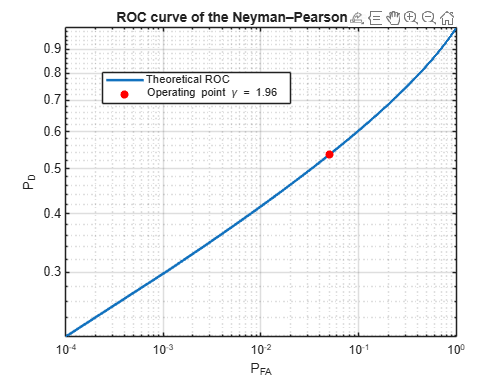

% We use the theoretical expressions from Task 2:
%   P_FA(gamma) = 2 Q(gamma / sigma0)
%   P_D(gamma)  = 2 Q(gamma / sigma1)
% To draw the ROC, we express P_D as a function of P_FA.

sigma0 = 1;          % std under H0  (sigma_0^2 = 1)
sigma1 = sqrt(10);   % std under H1  (sigma_1^2 = 10)

% Generate target false-alarm probabilities

% Hint from the assignment: use many P_FA values between 0 and 1.
% We avoid exactly 0 and 1 because Q^{-1} is not defined there.
PFA_vec = linspace(1e-4, 1-1e-4, 1000);   % 1000 points in (0,1)

% Compute corresponding detection probabilities using theory

% For each P_FA = alpha:
%   1) gamma(alpha) = sigma0 * Q^{-1}(alpha/2)
%   2) P_D(alpha)   = 2 Q( gamma(alpha) / sigma1 )
gamma_vec = sigma0 * qfuncinv(PFA_vec / 2);                 % step 1
PD_vec    = 2 * qfunc( (gamma_vec) / sigma1 );              % step 2

% Ploting ROC curve on log-log scale (as requested)

figure;
loglog(PFA_vec, PD_vec, 'LineWidth', 2);
grid on;
xlabel('P_{FA}');
ylabel('P_D');
title('ROC curve of the Neyman–Pearson detector');

% (Optional) Mark the operating point used in Tasks 3–5

% In Task 3 we used gamma = 1.96 (P_FA ≈ 0.05, P_D ≈ 0.54).
gamma_oper = 1.96;
PFA_oper = 2 * qfunc(gamma_oper / sigma0);
PD_oper  = 2 * qfunc(gamma_oper / sigma1);

hold on;
loglog(PFA_oper, PD_oper, 'ro', 'MarkerFaceColor','r');
legend('Theoretical ROC', 'Operating point \gamma = 1.96', 'Location','SouthWest');